## Best fit ciccio

df  = readtable("https://docs.google.com/spreadsheets/d/e/2PACX-1vTY7B7TP5M1YBscm1FWgLr80-TG4xaTxVTSYpG6w3wqSIAd2TXAQC3zl89G7bQzRqSjp-I405iVIAwk/pub?gid=486435952&single=true&output=csv")

df = 24×16 table
     x1      deltaX     y1     deltaY     x2      deltaX_1      y2       deltaY_1     x3      deltaX_2     y3     deltaY_2     x4      deltaX_3      y4      deltaY_3
    _____    ______    ____    ______    _____    ________    _______    ________    _____    ________    ____    ________    _____    ________    ______    ________

     1.25    0.0125    2.49     0.01      2.18     0.0218      2.6362      0.01       1.71     0.0171     

x1 = colnan(df.x1);
y1 = colnan(df.y1);
x2 = colnan(df.x2);
y2 = colnan(df.y2);
x3 = colnan(df.x3);
y3 = colnan(df.y3);
x4 = colnan(df.x4);
y4 = colnan(df.y4);

% incertezza su x e y
dx = 0.01;
dy = dx;

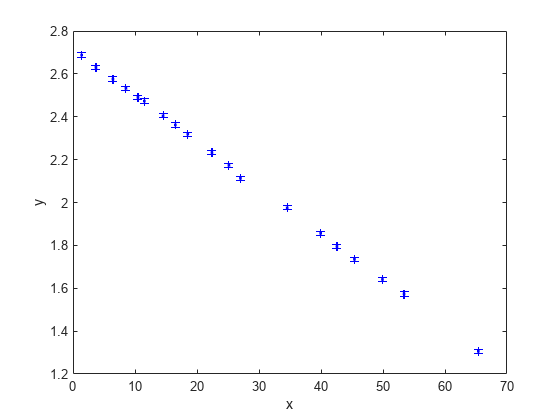

% scatterplot
n = 4;
x = x4;
y = y4;

s = sprintf("../img/scatter-ciccio-%i.png",n);

fig = figure;
errorbar(x,y,dy,dy,dx,dx,'.','Color','b')
xlabel("x")
ylabel("y")
saveas(fig,s)

n = 1

n = 1


id = (1:4)'

id =      1
     2
     3
     4


a = zeros(1,n)';
b = a, sigma_b = b, sigma_a = sigma_b;

b = 0

sigma_b = 0

i = 4

i = 4

x = x4;
y = y4;

[a(i), sigma_a(i), b(i), sigma_b(i)] = best_fit_mmq(x,y,true)

a =     2.6400    2.5000    2.7200    2.7150


sigma_a =     0.0080    0.3000    0.0100    0.0020


b =    -0.1218   -0.0230   -0.0930   -0.0215


sigma_b =     0.0007    0.0090    0.0009    0.0001




% [a, sigma_a, abs(sigma_a./a).*100, b, sigma_b, abs(sigma_b./b).*100]
% 
% T = table(id,latexerror(a,sigma_a), latexerror(b,sigma_b),'VariableNames',{'id','$q \pm \delta q$','$m \pm \delta m$'})
% exportLatexTable(T,"../ciccio-fit.tex")

%s = "ciccio." + string(i) + ".png"

dyv = repelem(dy,length(x))';

s = "bf-ciccio-" + string(i) + ".png"

s = "bf-ciccio-4.png"


yfit = a(i) + (b(i).*x);

chi = fitchisquarered(y,dy,yfit,2)

chi = 0.3591

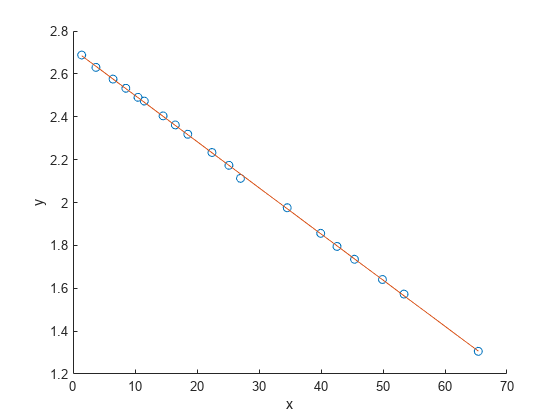


fig = figure;
scatter(x,y)
hold on
plot(x,yfit)
hold off
xlabel("x")
ylabel("y")

%saveas(fig,s)

chi

## Functions

function c = colnan(x)
    ni = isnan(x);
    c = x(~ni);
end

function r = bravpear(x,y)
    % coefficiente di Bravais-Pearson
    r = sum((x - repelem(mean(x),length(x),1))  .*  (y - repelem(mean(y),length(y),1))) ./ (  sqrt(sum((x - repelem(mean(x),length(x),1)).^2) .* sum((y - repelem(mean(y),length(y),1)).^2))  );
end

% uncertainty significative rounding
function dx = usiground(dx)
    % numero decimali
    n = abs(floor(log10(dx)));
    
    % lunghezza vettore dx
    l = length(dx);
    
    if l==1
        dx = round(dx,n);
    else
        scale_factor = power(10, n);
        dx = round(dx .* scale_factor) ./ scale_factor;
    end
end

% significative rounding
% siground(x,dx)
% x:  misura
% dx: incertezza
% Description: approssima al corretto numero di cifre decimali la misura x e
% l'incertezza dx. L'output sarà un numero e non un testo.
% usage: [x, dx] = siground(x,dx)
function [x, dx] = siground(x,dx)
    % calcola numero di decimali
    n = abs(floor(log10(dx)));
    
    % calcola dimensione vettore
    l = length(n);

    if l==1
        % approssima incertezza
        dx = round(dx,n);

        % approssima misura
        x = round(x,n);
    else
        %disp("Vettori non ancora supportati del tutto. Da testare")
        scale_factor = power(10, n);
        dx = round(dx .* scale_factor) ./ scale_factor;
        x  = round(x .* scale_factor) ./ scale_factor;
    end
end

% determina i coefficienti della best-fit line utilizzando il metodo dei
% minimi quadrati
function [a, sigma_a, b, sigma_b] = best_fit_mmq(x,y,f)
    % f: flag rounding, true or false

    % best fit lineare nella forma
    % y = A + Bx

    % numero di punti
    n = length(x);
    
    delta = n.*sum(x.^2) - (sum(x)).^2;
    
    % intercetta
    a = (   (sum(x.^2).*sum(y))  - (sum(x).*sum(x.*y))   )./delta;

    % coefficiente angolare
    b = (   (n.*sum(x.*y)) - (sum(x).*sum(y))   )./delta;

    % sigma y eq 8.15 Taylor
    sigma_y = sqrt(sum((y - repelem(a,n,1) - repelem(b,n,1).*x).^2)./(n - 2)); %sigma_y = round(sigma_y,2)

    % errore su a eq. 8.16 Taylor
    sigma_a = sigma_y .* sqrt((sum(x.^2))./(delta));

    % errore su b eq. 8.17 Taylor
    sigma_b = sigma_y .* sqrt(n./delta);
    
    % arrotondo sulla scelta utente
    if f == true
        sigma_a = usiground(sigma_a);
        sigma_b = usiground(sigma_b);
        a = siground(a,sigma_a);
        b = siground(b,sigma_b);
    end
end

% determina i coefficienti della best-fit line utilizzando il metodo dei
% minimi quadrati pesata. Formule della pagina 201 del Taylor
function [a, sigma_a, b, sigma_b] = weighted_best_fit_mmq(x,y,dy,f)
    % f: flag rounding, true or false

    % best fit lineare nella forma
    % y = A + Bx
    
    % pesi
    w = 1./dy.^2;
    
    % denominatore eq. 8.39 Taylor
    delta = (sum(w).*sum(w.*x.^2)) - (sum(w.*x)).^2;
    
    % intercetta eq. 8.37 Taylor
    a = (   (sum(w.*x.^2).*sum(w.*y))  - (sum(w.*x).*sum(w.*x.*y))   )./delta;

    % coefficiente angolare eq. 8.38 Taylor
    b = (   (sum(w).*sum(w.*x.*y)) - (sum(w.*x).*sum(w.*y))   )./delta;

    % errore su a
    sigma_a = sqrt((sum(w.*x.^2))./delta);

    % errore su b
    sigma_b = sqrt(sum(w)./delta);
    
    % arrotondo sulla scelta utente
    if f == true
        sigma_a = usiground(sigma_a);
        sigma_b = usiground(sigma_b);
        a = siground(a,sigma_a);
        b = siground(b,sigma_b);
    end
end

% approssima misura e incertezza allo stesso numero di cifre significative
% e converti in testo
% input
% x:  misura
% dx: incertezza misura
function [tx, tdx] = single_signum2str(x,dx)
    
    % calcolo numero di cifre a cui approssimare
    n = abs(floor(log10(dx)));

    % tdx = num2str(round(dx,n));
    tdx = num2str(usiground(dx));

    % costruisco formato dinamico (e.g. %.4f)
    formato = ['%.', num2str(n), 'f'];

    % creo stringa
    tx = sprintf(formato, x);
end

function [tx, tdx] = signum2str(x,dx)
    % fa la stessa cosa di signum2str(x,dx) ma opera su x e dx vettoriali
    % della stessa lunghezza

    % calcola lunghezza x e dx
    if length(x) == length(dx)
        l = length(x);
        
        % se il vettore è di lunghezza 1, ovvero è uno scalare, usa la
        % funzione single_signum2str(). 
        % Questo generalizza signum2str() che
        % si può usare sia nel caso scalare che vettoriale

        if l==1
            [tx, tdx] = single_signum2str(x,dx);
        else
            % inizializza array di stringhe
            tx = strings(l,1);
            tdx = tx;
    
            for i=1:l
                [tx(i), tdx(i)] = signum2str(x(i),dx(i));
            end
        end
    else
        disp("Error: length mismatch")
    end
end

% chi quadro di un fit
function chi = fitchisquarered(y,dy,yfit,params)
    chi = sum(((yfit-y)./dy).^2)./(length(y)-params);
end

% formatta valore \pm misura come latex
% misura e errore devono essere stringhe
function text = latexerror(misura,errore)
    if isnumeric(misura) && isnumeric(errore)
        [tmisura, terrore] = signum2str(misura,errore);
        text = "$" + tmisura + " \pm " + terrore + "$";
    else
        if ischar(misura) && ischar(errore)
            text = "$" + misura + " \pm " + errore + "$";
        end
    end
end

function exportLatexTable(tableData, fileName)
    % Apri il file in modalità scrittura
    fileID = fopen(fileName, 'w');
    
    % Ottieni il numero di colonne della tabella
    numCols = size(tableData, 2);
    
    % Ottieni le intestazioni della tabella
    headers = string(tableData.Properties.VariableNames);

    % Scrivi l'intestazione della tabella LaTeX
    fprintf(fileID, '\\begin{longtable}{@{}');
    for i = 1:numCols
        fprintf(fileID, 'l');
    end
    fprintf(fileID, '@{}}\n');
    
    % Scrivi l'intestazione delle colonne
    fprintf(fileID, '\\toprule\n');
    for i = 1:numCols
        fprintf(fileID, '%s', headers(i));
        if i < numCols
            fprintf(fileID, ' & ');
        else
            fprintf(fileID, ' \\tabularnewline\n');
        end
    end
    
    % Scrivi la riga divisoria
    fprintf(fileID, '\\midrule\n');
    
    % Scrivi i dati della tabella
    for row = 1:size(tableData, 1)
        for col = 1:numCols
            % Sostituisci "data" con i valori effettivi della tabella
            fprintf(fileID, '%s', string(table2cell(tableData(row, col))));
            if col < numCols
                fprintf(fileID, ' & ');
            else
                fprintf(fileID, ' \\tabularnewline\n');
            end
        end
    end
    
    % Scrivi la riga finale della tabella LaTeX
    fprintf(fileID, '\\bottomrule\n');
    
    % Scrivi etichetta e caption della tabella
    fprintf(fileID, '\\label{tab:edithere}\n');
    fprintf(fileID, '\\\\');
    fprintf(fileID, '\n\\caption{edithere}\n');
    fprintf(fileID, '\\end{longtable}\n');

    % Chiudi il file
    fclose(fileID);
    
    fprintf('Tabella LaTeX esportata correttamente nel file "%s".\n', fileName);
end

function e = texreler(measure,uncertainty)
    e = round(100.*(uncertainty./measure),2);
    e = string(e) + "\%";
end

function [e, de] = weightedaverage(measure, uncertainty,flag)
    % input
    % measure: vettore contenente le misure da mediare
    % incertezza: vettore contenente le incertezze sulle misure
    % flag: se true, allora approssima il risultato sulla base del numero
    % di cifre significative dell'errore della media pesata.

    % output
    % e: media pesata
    % de: errore sulla media
    
    % assegno pesi
    w = 1./(uncertainty.^2);
    
    % calcolo media ed errore
    e   = sum(w.*measure) ./ sum(w);
    de  = sqrt(1./sum(w));

    % approssima
    if flag==true
        [e, de] = siground(e,de);
    end
end
